auv_pos = [0; 0; -5];
auv_vel = [0; 0; 0];
capsule_vel = [0; 0; 3];
uav_pos = [0; 0; 50];
uav_vel = [0; 0; 5];

% Define AUV position and tether length
tether_length = 50;
capsule_pos = auv_pos;

% Set simulation parameters
dt = 0.01;
t_end = 30;
t = 0;

% Define proximity threshold range
proximity_threshold_min = 0;
proximity_threshold_max = 10;

% Initialize flags
capsule_on_surface = false;
signal_transmitted = false;
uav_in_vicinity = false;
uav_message_received = false;
uav_in_proximity = false;
mission_complete = false;

% Set up figure window
fig = figure;
axis([-100 100 -100 100 -100 250]);
hold on;
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
view(45, 45);
set(gca, 'ZDir', 'normal');

% Define water surface color and transparency
water_color = [0.5 0.5 1];
water_alpha = 0.5;

% Plot water surface
water_surface = fill3([-100 -100 100 100], [-100 100 100 -100], [0 0 0 0], water_color, 'FaceAlpha', water_alpha);

% Plot AUV, capsule, and UAV
auv_obj = scatter3(auv_pos(1), auv_pos(2), auv_pos(3), 200, 'filled', 'bo');
capsule_obj = scatter3(capsule_pos(1), capsule_pos(2), capsule_pos(3), 100, 'filled', 'r');
uav_obj = scatter3(uav_pos(1), uav_pos(2), uav_pos(3), 150, 'filled', 'g');

% Plot trajectory of capsule and UAV
capsule_traj = plot3(capsule_pos(1), capsule_pos(2), capsule_pos(3), 'r');
uav_traj = plot3(uav_pos(1), uav_pos(2), uav_pos(3), 'g');

while t < t_end && ~mission_complete
    % Update AUV position and velocity
    auv_pos = auv_pos + auv_vel * dt;
    auv_obj.XData = auv_pos(1);
    auv_obj.YData = auv_pos(2);
    auv_obj.ZData = auv_pos(3);
    
    capsule_obj.XData = capsule_pos(1);
    capsule_obj.YData = capsule_pos(2);
    capsule_obj.ZData = capsule_pos(3);
    
    % Update capsule trajectory
    capsule_traj.XData = [capsule_traj.XData, capsule_pos(1)];
    capsule_traj.YData = [capsule_traj.YData, capsule_pos(2)];
    capsule_traj.ZData = [capsule_traj.ZData, capsule_pos(3)];
    
% Ascend capsule to surface
for i = 1:100
    capsule_pos = capsule_pos + [0; 0; 1];
    disp(['Capsule ascending: ', num2str(capsule_pos(3)), 'm']);

    % Add animation of tethering capsule from AUV
    num_steps = 50;
    tether_points = [capsule_pos, capsule_pos + [0; 0; 5]];
    uav_points = [uav_pos, uav_pos + [0; 0; -10]];

     pause(0.05);

    for j = 1:num_steps
        tether_points(:,2) = tether_points(:,2) + [0; 0; -1/num_steps];
        uav_points(:,2) = uav_points(:,2) + [0; 0; 1/num_steps];

        plot3(tether_points(1,:), tether_points(2,:), tether_points(3,:), 'r');
        plot3(uav_points(1,:), uav_points(2,:), uav_points(3,:), 'g');
        drawnow;
        pause(0.05);
    end

    % Update capsule position and check if it has reached the surface
    if capsule_pos(3) == 0 && ~capsule_on_surface
        capsule_on_surface = true;
        disp('Capsule stopping ascent');
        disp('Capsule has reached surface'); 
    end
    
    % Break the loop if the capsule has reached the surface
    if capsule_on_surface && norm(uav_pos(3)-capsule_pos(3))>= proximity_threshold_max
        uav_in_proximity = false;
        disp('UAV must take off to reach proximity zone') 
        
     for k=i:100
         uav_pos = uav_pos + [0;0;-5];
         % Update UAV position and velocity
         uav_pos = uav_pos + uav_vel * dt;
         uav_vel = [10 0 10]; % UAV velocity initialized to zero
         disp(['UAV Arriving: ', num2str(uav_pos(3)), 'm']);
         pause(0.5);
     % Check if UAV is in proximity to capsule
if norm(uav_pos - capsule_pos) >= proximity_threshold_min && norm(uav_pos(3) - capsule_pos(3)) <= proximity_threshold_max && uav_pos(3) >= capsule_pos(3)
    uav_in_proximity = true;
    disp('UAV is in proximity to capsule');
    
    break;
else
    disp('UAV is not in proximity, attempt again')

    % Update UAV trajectory
        uav_traj.XData = [uav_traj.XData, uav_pos(1)];
        uav_traj.YData = [uav_traj.YData, uav_pos(2)];
        uav_traj.ZData = [uav_traj.ZData, uav_pos(3)];
end
     end
        break;
    end
end

% Check if mission is complete
if uav_in_proximity
mission_complete = true;
disp('Mission complete!');
end

t = t + dt;
end

Capsule ascending: -4m


Capsule ascending: -3m
Capsule ascending: -2m
Capsule ascending: -1m
Capsule ascending: 0m


Capsule stopping ascent


Capsule has reached surface


UAV must take off to reach proximity zone


UAV Arriving: 45.05m


UAV is not in proximity, attempt again


UAV Arriving: 40.15m


UAV is not in proximity, attempt again


UAV Arriving: 35.25m


UAV is not in proximity, attempt again


UAV Arriving: 30.35m


UAV is not in proximity, attempt again


UAV Arriving: 25.45m


UAV is not in proximity, attempt again


UAV Arriving: 20.55m


UAV is not in proximity, attempt again


UAV Arriving: 15.65m


UAV is not in proximity, attempt again


UAV Arriving: 10.75m


UAV is not in proximity, attempt again


UAV Arriving: 5.85m


UAV is in proximity to capsule


Mission complete!


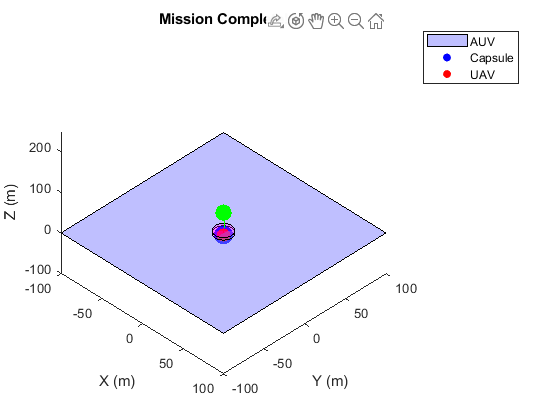



% Plot shaded zone of communication establishment
theta = linspace(0, 2*pi);
x = proximity_threshold_max*cos(theta);
y = proximity_threshold_max*sin(theta);
z1 = zeros(size(theta));
z2 = ones(size(theta))*(uav_pos(3)-capsule_pos(3));
shaded_zone = fill3(x, y, [z1;z2;z1], 'm', 'FaceAlpha', 0.3, 'EdgeColor', 'k');

% Finalize plot
if mission_complete
title('Mission Complete!');
else
title('Mission Failed');
end
legend('AUV', 'Capsule', 'UAV')

hold off;

% Display messages sent and received
if mission_complete
disp('Messages sent:');
disp('Capsule: Capsule has reached surface');
disp('UAV: UAV is in vicinity of capsule');
disp('Capsule: Capsule has transmitted message to UAV');

% Check if UAV has received message
if mission_complete
    uav_message_received = true;
    decrypt_message = input('Press 1 to decrypt message: ');
    if decrypt_message == 1
        disp('Messages received:');
       disp('UAV: UAV has received message from capsule');
       disp('Capsule: Hi UAV, I have some information, that was a ship');
    end
end

else
    disp('Messages not received:');
    disp('UAV: UAV has not received message from capsule');
   disp('Capsule: Cannot Transmit');
end

Messages sent:


Capsule: Capsule has reached surface


UAV: UAV is in vicinity of capsule


Capsule: Capsule has transmitted message to UAV


Messages received:


UAV: UAV has received message from capsule


Capsule: Hi UAV, I have some information, that was a ship
